# Linear Control Design II - Group Work Problem Module 3 Solution

## Description

This exercise is based on the work carried out in the Group Work Problem Module 2. For the electro-mechanical system illustrated in Figure 1 and described in Group Work Problem Module 2 the goals for this assignment is: a) linearize the electromagnetic force resulted from the change in current and change in displacement. I.e. $Ki$ and $Ks$; b) derive the SISO state space model ($\textbf{A}$, $\textbf{B}$, $\textbf{C}$ & $\textbf{D}$) for the electro-mechanical system using the state parameters


$$\textbf{x}=[q_1,q_2,q_3,q_4,q_5,q_6,q_7]^T=[i,x_1,\dot{x}_1,x_2,\dot{x}_2,x_3,\dot{x}_3]^T$$


where


$$\dot{\textbf{x}}=\textbf{A}\textbf{x}+\textbf{Bu}\\\textbf{y}=\textbf{C}\textbf{x}+\textbf{Du}$$


c)  investigate the vibrations of the structure when different initial conditions and inputs are present and compare with the results from Group Work Module 2;

d) compare the obtained results from Group Work Module 2 with the results from this Group Work Module.

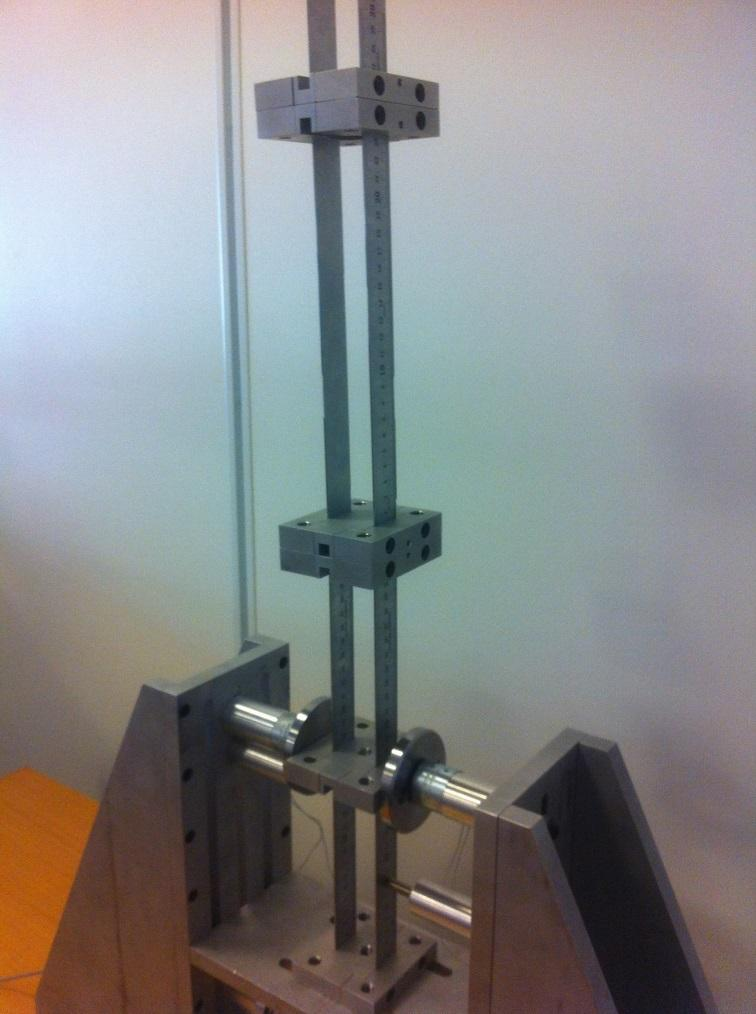


$$Figure\,1:\,Electro-mechanical\,system\,composed\,of\,three\,masses\,interconnected\\ by\,flexible\,beams\,(mechanical parts)\,and\,a\,pair\,of\,electromagnets\,(electrical parts).$$


**Problem 1**

Linearize the electromagnetic force resulted from the change in current and change in displacement.

Define $Ki$ and $Ks$

**Solution****:**

The electromagnetic force derived by $i(t)$ yields $Ki$.

The electromagnetic force derived by $x(t)$ yields $Ks$.

$Ki$ and $Ks$ from slides given below.

syms mu N A ib x0
Ki = mu*N^2*A*ib / x0^2

$$Ki = \frac{A\,N^{2}\,\mathrm{ib}\,\mu }{{x_{0}}^{2}}$$

Ks = -mu*N^2*A*(ib^2)/x0^3

$$Ks = -\frac{A\,N^{2}\,{\mathrm{ib}}^{2}\,\mu }{{x_{0}}^{3}}$$

**Problem 2**

Derive the SISO state space model ($\textbf{A}$, $\textbf{B}$, $\textbf{C}$ & $\textbf{D}$) for the electro-mechanical system using the state parameters


$$\textbf{x}=[q_1,q_2,q_3,q_4,q_5,q_6,q_7]^T=[i,x_1,\dot{x}_1,x_2,\dot{x}_2,x_3,\dot{x}_3]^T$$


where


$$\dot{\textbf{x}}=\textbf{A}\textbf{x}+\textbf{Bu}\\\textbf{y}=\textbf{C}\textbf{x}+\textbf{Du}$$


**Solution****:**

The time dependent variables are arranged into the defined state vector and the electro-mechanical model is arranged into the state space matrices ($\textbf{A}$, $\textbf{B}$, $\textbf{C}$ & $\textbf{D}$). The resulting matrices are illustrated in Figure 2.

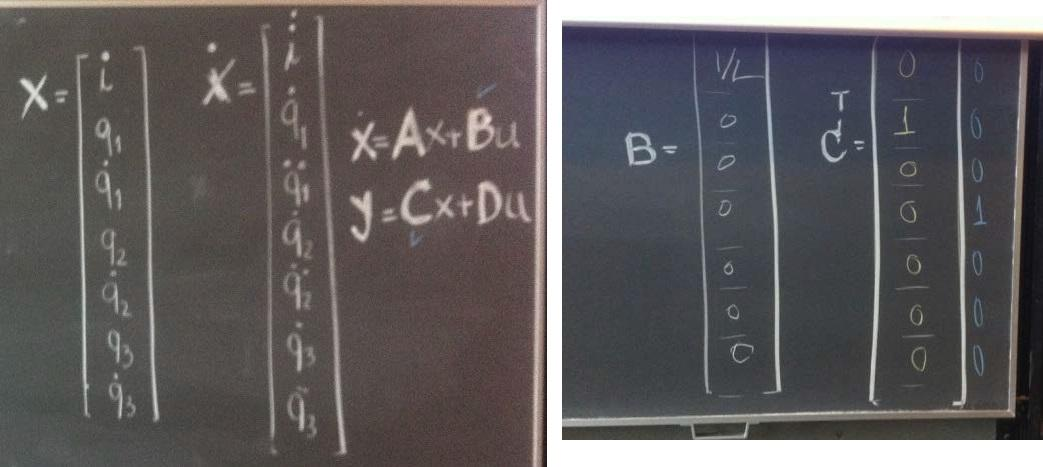


$$a)\,\quad\quad\quad\quad\quad\quad\quad\quad\quad\quad\quad\quad\quad\quad\quad\,b)$$


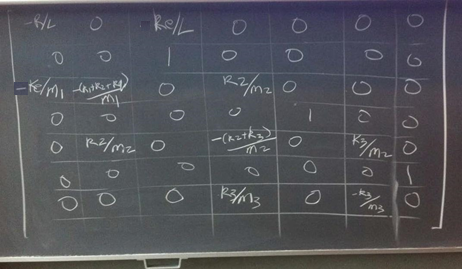


$$c)$$



$$Figure\,2:\,a)\,The\,arrangement\,of\,the\,states\,and\,the\,form\,of\,the\,state\,space\,model\\are\,shown;\,
b)\,the\,\textbf{B}-and\,\textbf{C}-matrices\,is\,presented;\,c)\,the\,\textbf{A}-matrix\,is\,illustrated.$$


syms R L K_i K_s m1 m2 m3 k1 k2 k3

Ax = [
        -R/L        0         K_i/L       0         0    0   0
          0         0             1       0         0    0   0
       -K_i/m1 -(k1+k2+K_s)/m1    0     k2/m1       0    0   0
          0         0             0       0         1    0   0
          0       k2/m2           0  -(k2 + k3)/m2  0  k3/m2 0
          0         0             0       0         0    0   1
          0         0             0     k3/m3       0 -k3/m3 0 ]

$$Ax = \left(\begin{array}{ccccccc} -\frac{R}{L} & 0 & \frac{K_{i}}{L} & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0 & 0\\ -\frac{K_{i}}{m_{1}} & -\frac{K_{s}+k_{1}+k_{2}}{m_{1}} & 0 & \frac{k_{2}}{m_{1}} & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & \frac{k_{2}}{m_{2}} & 0 & -\frac{k_{2}+k_{3}}{m_{2}} & 0 & \frac{k_{3}}{m_{2}} & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & \frac{k_{3}}{m_{3}} & 0 & -\frac{k_{3}}{m_{3}} & 0 \end{array}\right)$$

      
Bx = [   1/L  0   0   0   0   0   0 ]'

$$Bx = \left(\begin{array}{c} \frac{1}{\bar{L}}\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$


Cx = [   0    1   0   0   0   0   0 ]

Cx =      0     1     0     0     0     0     0



Dx = 0;


Here we have chosen as output the position of the first mass. We could have chosen another state variable by placing the 1 in $\textbf{C}$ matrix in an other position or even change the dimensions of the matrix, so that we can measure more than one state variables like in the following selection of the output matrix, where we can obtain both the position and the velocity of the first mass.

C1 = [   0    1   0   0   0   0   0 
         0    0   1   0   0   0   0 ]

C1 =      0     1     0     0     0     0     0
     0     0     1     0     0     0     0


**Problem 3**

The goal of the problem is to investigate how the structure behaves when $s_0$ (air gap) is varied from 5 mm to 1 mm. The initial conditions of lateral displacements  $x_2(0)$, $x_3(0)$ and  velocities  $\dot{x}_1(0)$, $\dot{x}_2(0)$, $\dot{x}_3(0)$ are zero and kept for all simulation cases. Only the  lateral displacement of the lowest mass $x_1(0)$ is offset by 1 mm from center. Simulate three different values of $s_0$=5 mm, $s_0$=3 mm, $s_0$=1 mm. Explain the simulation results.

**Solution****:**

The simulations can be carried out in simulink using matrix products as in the simulink diagram presented in Fiugre 3.

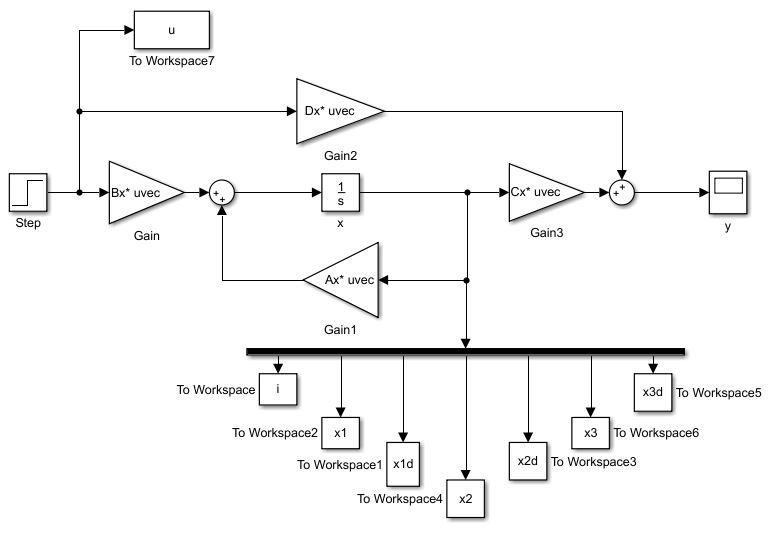


$$Figure\,3:\,Simulink\,block\,diagram\,of\,the\,state\,space\,model$$


**a) **Behavior of system when $s_0$=5 mm.

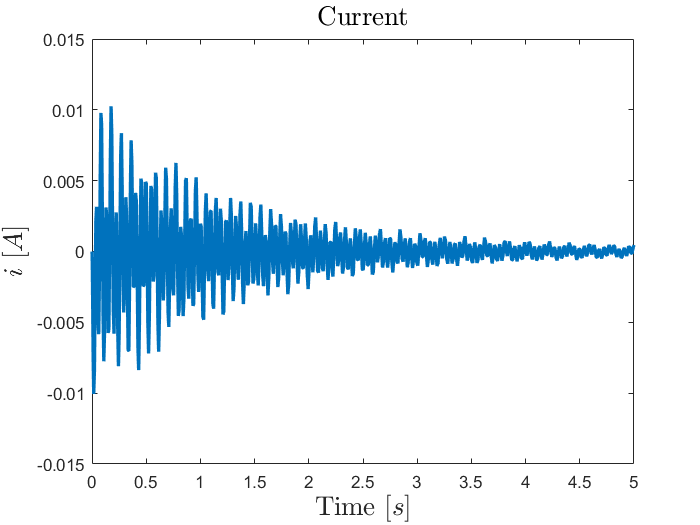

% Parameters
m1 = 0.712;         % [kg] mass of platform 1
m2 = 0.428;         % [kg] mass of platform 1
m3 = 0.428;         % [kg] mass of platform 1

l = 24e-3; % mm, small
r = 14e-3 / 2;
A = pi*r^2;
R = 148.2;
L = 800e-3; % [H]
iMax = 0.14; % measured at 24v

gam = 0.5;          % bias ratio - normally chosen between 0.2-0.5
ib = iMax*gam;      % Bias current
mu = 4*pi*1e-7;     % Permeability of free space (vacuum)
x0 = 5e-3;          % displacement operation point

b = 0.025;          % [m] beam width
h = 1.0e-3;         % [m] beam thickness
N = sqrt(L*2*x0 / (mu*A)); % estimate number of windings based on above formular
E = 2.0e11;         % [N/m2] elasticity modulus of steel
Iz = (b*h^3)/12;    % [m4] area moment of inertia

L1= 0.145;           % [m] length of beam 1
L2= 0.134;           % [m] length of beam 2
L3= 0.229;           % [m] length of beam 3

% Force constants obtained from the linearisation

k1 = 2*12*E*Iz/L1^3;   % [N/m] stiffness of beam 1
k2 = 2*12*E*Iz/L2^3;   % [N/m] stiffness of beam 2
k3 = 2*12*E*Iz/L3^3;   % [N/m] stiffness of beam 3

Ki = mu*N^2*A*ib / x0^2;
Ks = -mu*N^2*A*(ib^2)/x0^3;

Ax = [
        -R/L        0          Ki/L       0         0    0   0
          0         0             1       0         0    0   0
       -Ki/m1 -(k1+k2+Ks)/m1      0     k2/m1       0    0   0
          0         0             0       0         1    0   0
          0       k2/m2           0  -(k2 + k3)/m2  0  k3/m2 0
          0         0             0       0         0    0   1
          0         0             0     k3/m3       0 -k3/m3 0 ];
      
Bx = [   1/L  0   0   0   0   0   0 ]';

Cx = [   0    1   0   0   0   0   0 ];

Dx = 0;

% initial conditions
x_0 = [0 0.001 0 0 0 0 0]';

% input
u_0 = 0;


%% Simulations
sim('electroMagnetModelStateSpace');

%% Plots
time = i.time;

figure
plot(time,i.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$i$ $[A]$', 'FontSize',16,'Interpreter','latex');
title('Current', 'FontSize',16,'Interpreter','latex');

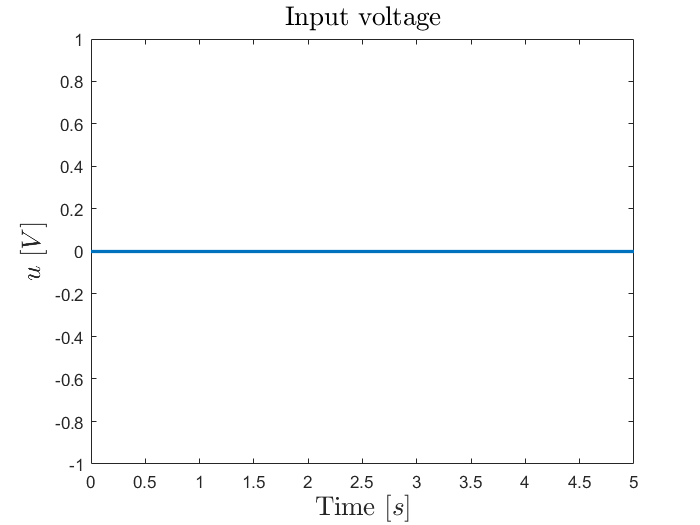


figure
plot(time,u.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$u$ $[V]$', 'FontSize',16,'Interpreter','latex');
title('Input voltage', 'FontSize',16,'Interpreter','latex');

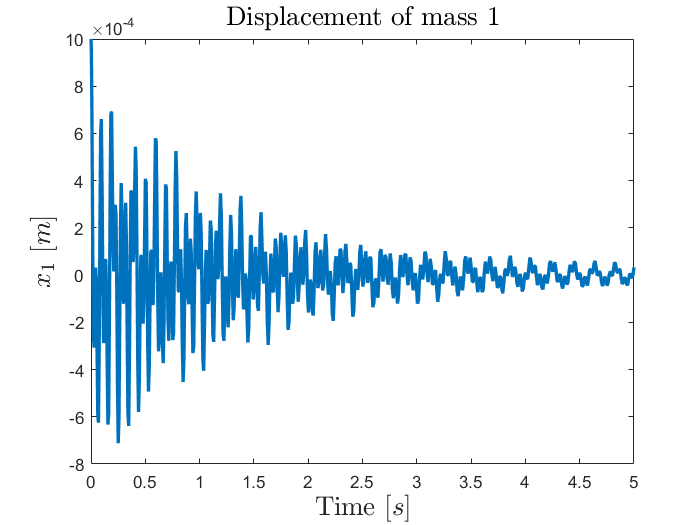


figure
plot(time,x1.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_1$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 1', 'FontSize',16,'Interpreter','latex');

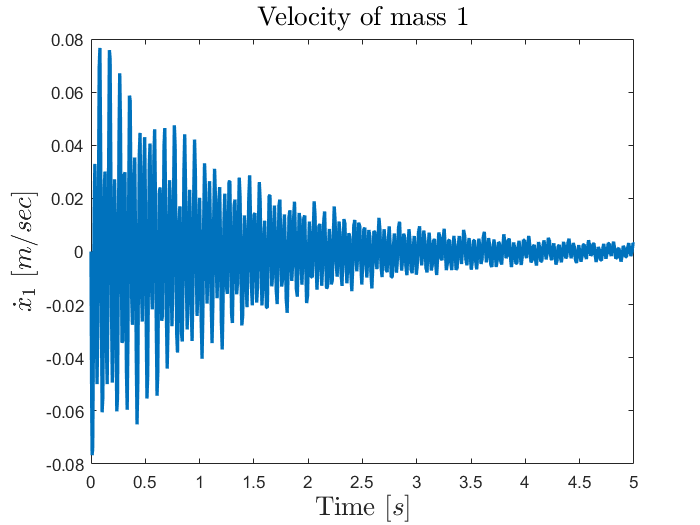


figure
plot(time,x1d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_1$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 1', 'FontSize',16,'Interpreter','latex');

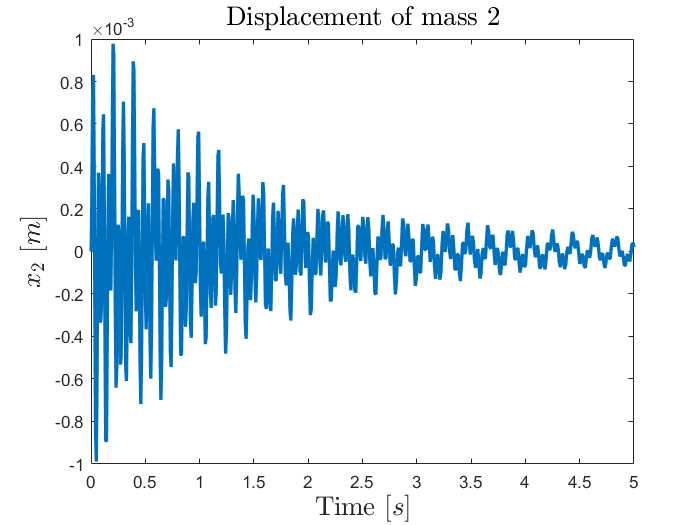


figure
plot(time,x2.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_2$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 2', 'FontSize',16,'Interpreter','latex');

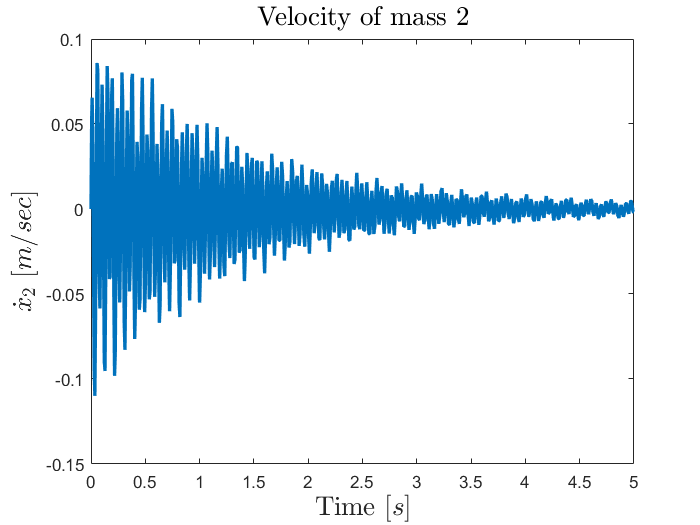


figure
plot(time,x2d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_2$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 2', 'FontSize',16,'Interpreter','latex');

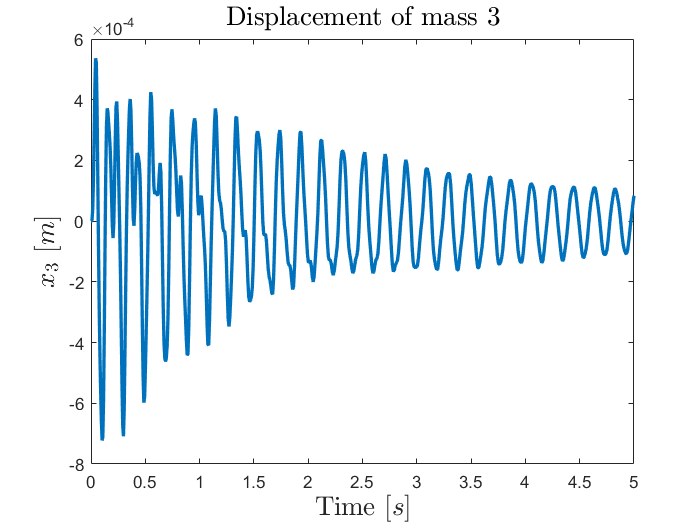


figure
plot(time,x3.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_3$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 3', 'FontSize',16,'Interpreter','latex');

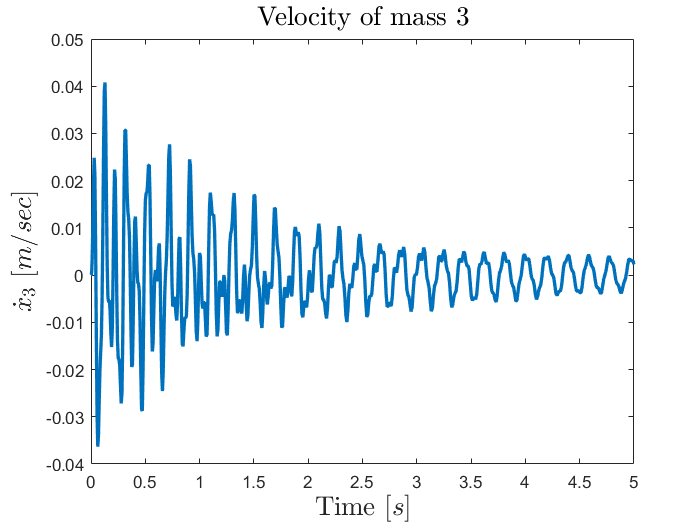


figure
plot(time,x3d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_3$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 3', 'FontSize',16,'Interpreter','latex');

As we can see in the plots, when there is no external input (voltage or forces) acting on the system, the responses decay over time to their equilibrium positions, i.e. zero displacement,  zero velocity and zero current. This is expected, since the system is very similar to the mass-spring-damper system. After approximately 10 seconds all the transient behaviors of the states have died out and the state settle to its equilibrium point $\textbf{x}(t) = [0\; 0\; 0\;  0\;  0 \;0 \; 0]^T$.

**b) **Behavior of system when $s_0$=3 mm.

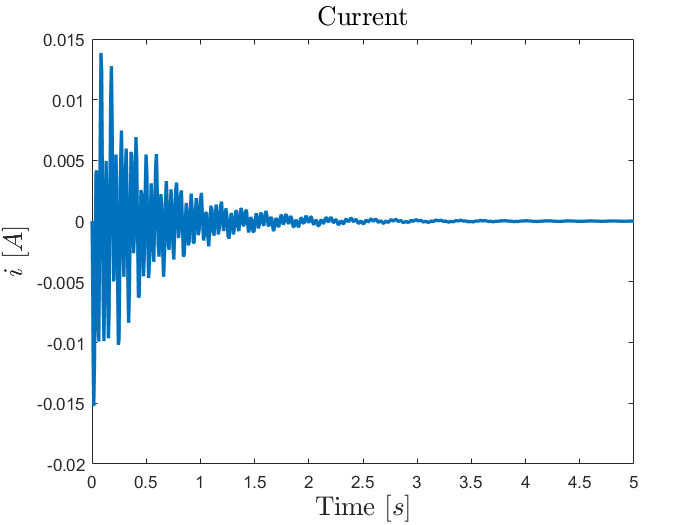

x0 = 3e-3;          % displacement operation point

N = sqrt(L*2*x0 / (mu*A)); % estimate number of windings based on above formular

Ki = mu*N^2*A*ib / x0^2;
Ks = -mu*N^2*A*(ib^2)/x0^3;

Ax = [
        -R/L        0          Ki/L       0         0    0   0
          0         0             1       0         0    0   0
       -Ki/m1 -(k1 + k2 + Ks)/m1  0     k2/m1       0    0   0
          0         0             0       0         1    0   0
          0       k2/m2           0  -(k2 + k3)/m2  0  k3/m2 0
          0         0             0       0         0    0   1
          0         0             0     k3/m3       0 -k3/m3 0 ];
      
%% Simulations
sim('electroMagnetModelStateSpace');

%% Plots
time = i.time;

figure
plot(time,i.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$i$ $[A]$', 'FontSize',16,'Interpreter','latex');
title('Current', 'FontSize',16,'Interpreter','latex');


figure
plot(time,u.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$u$ $[V]$', 'FontSize',16,'Interpreter','latex');
title('Input voltage', 'FontSize',16,'Interpreter','latex');

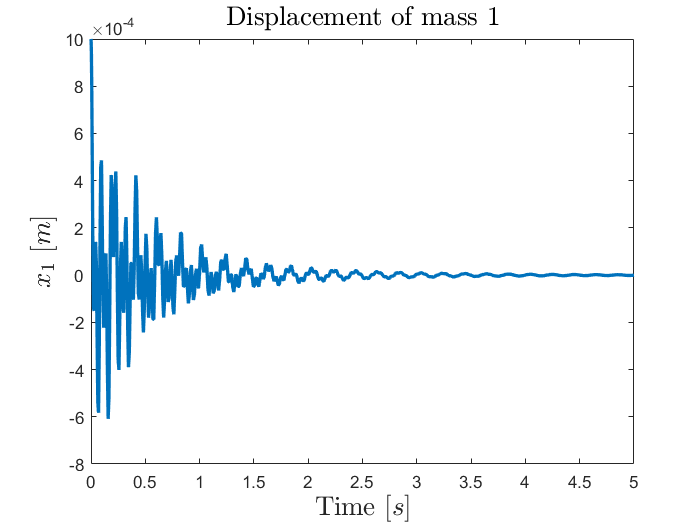


figure
plot(time,x1.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_1$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 1', 'FontSize',16,'Interpreter','latex');

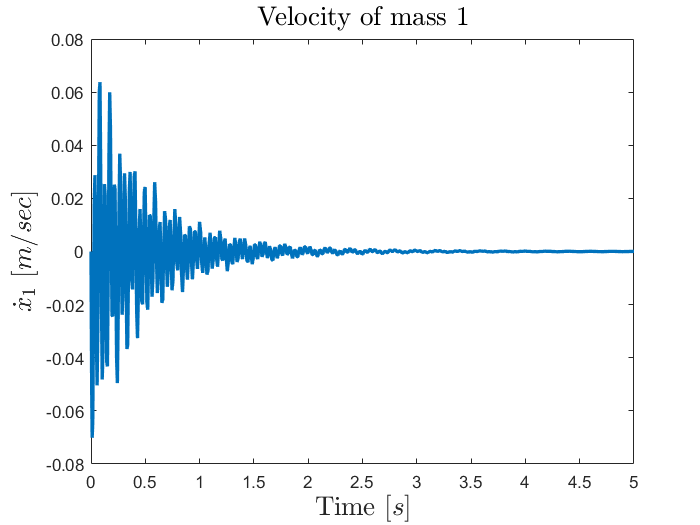


figure
plot(time,x1d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_1$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 1', 'FontSize',16,'Interpreter','latex');

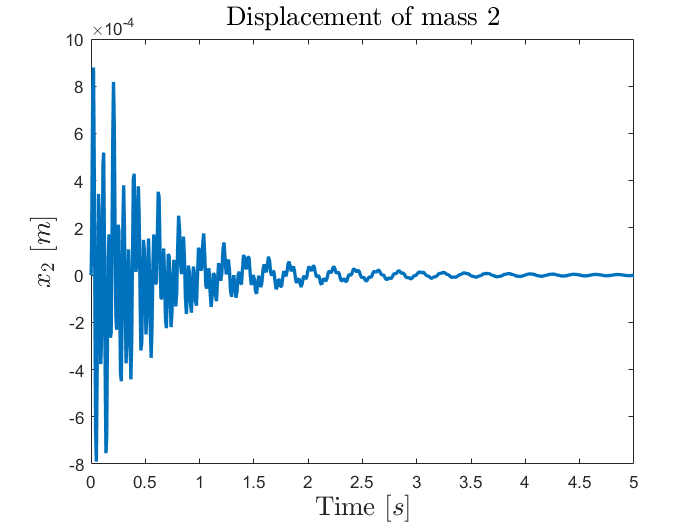


figure
plot(time,x2.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_2$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 2', 'FontSize',16,'Interpreter','latex');

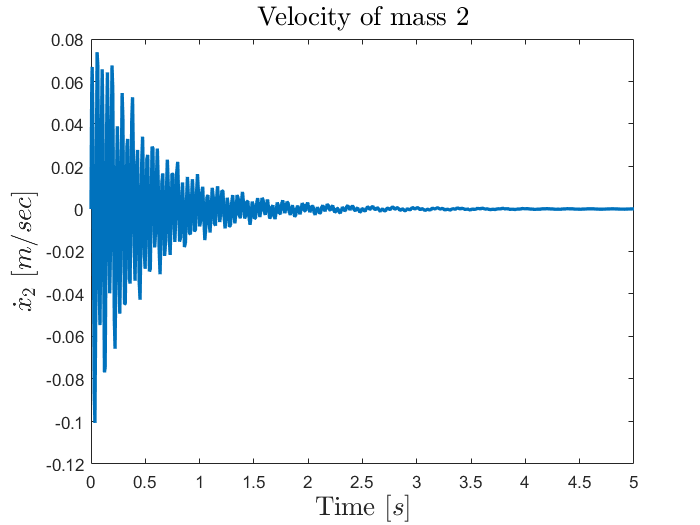


figure
plot(time,x2d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_2$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 2', 'FontSize',16,'Interpreter','latex');

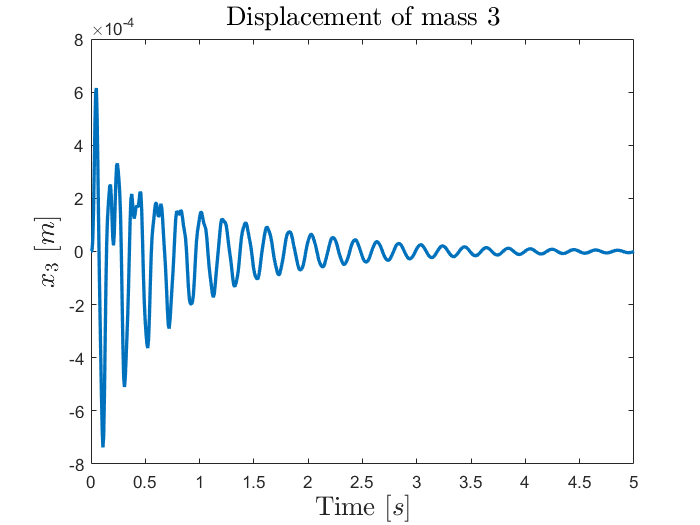


figure
plot(time,x3.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_3$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 3', 'FontSize',16,'Interpreter','latex');

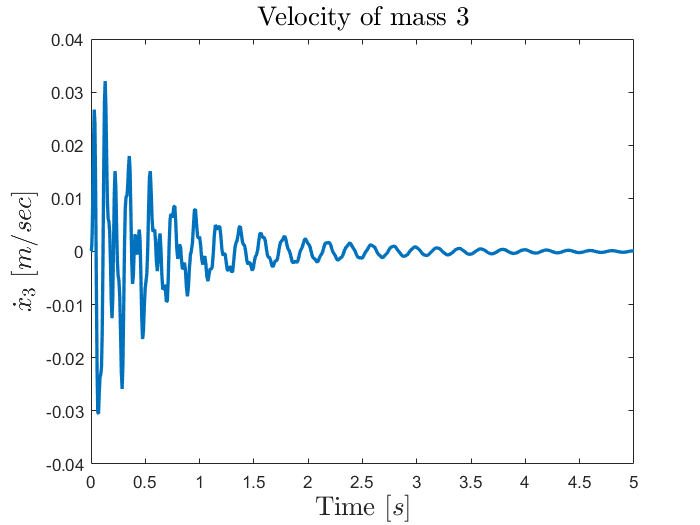


figure
plot(time,x3d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_3$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 3', 'FontSize',16,'Interpreter','latex');

The behavior of the system is similar to the previous case with the difference that the state variables now settle to their equilibrium positions much faster, almost in 3 seconds. This can be explained by the fact that smaller air gaps between the lowest mass and the magnets generate larger magnetic forces, which in turn drive the system dynamics faster. This can be also deducted from the equation describing the magnetic force.


$$f=\frac{\mu_0n^2A_0}{4}\left(\frac{(i_0+i(t))^2}{(s_0-x_1(t))^2}-\frac{(i_0+i(t))^2}{(s_0+x_1(t))^2}\right)$$


**c) **Behavior of system when $s_0$=1 mm.

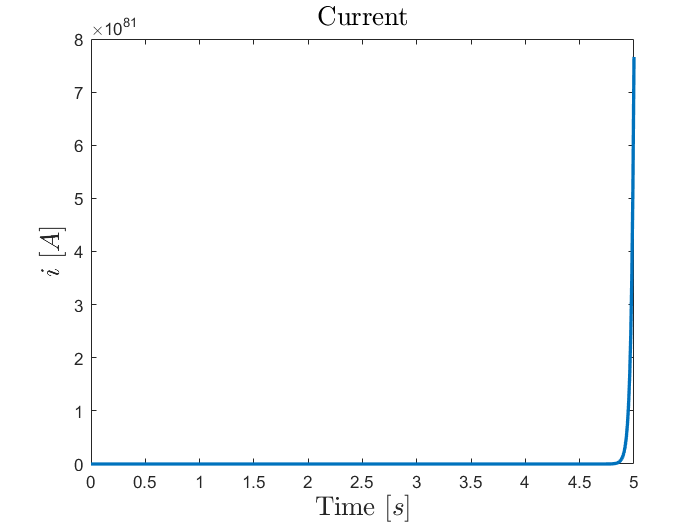

x0 = 1e-3;          % displacement operation point

N = sqrt(L*2*x0 / (mu*A)); % estimate number of windings based on above formular

Ki = mu*N^2*A*ib / x0^2;
Ks = -mu*N^2*A*(ib^2)/x0^3;

Ax = [
        -R/L        0          Ki/L       0         0    0   0
          0         0             1       0         0    0   0
       -Ki/m1 -(k1 + k2 + Ks)/m1  0     k2/m1       0    0   0
          0         0             0       0         1    0   0
          0       k2/m2           0  -(k2 + k3)/m2  0  k3/m2 0
          0         0             0       0         0    0   1
          0         0             0     k3/m3       0 -k3/m3 0 ];
      
%% Simulations
sim('electroMagnetModelStateSpace');

%% Plots
time = i.time;

figure
plot(time,i.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$i$ $[A]$', 'FontSize',16,'Interpreter','latex');
title('Current', 'FontSize',16,'Interpreter','latex');


figure
plot(time,u.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$u$ $[V]$', 'FontSize',16,'Interpreter','latex');
title('Input voltage', 'FontSize',16,'Interpreter','latex');

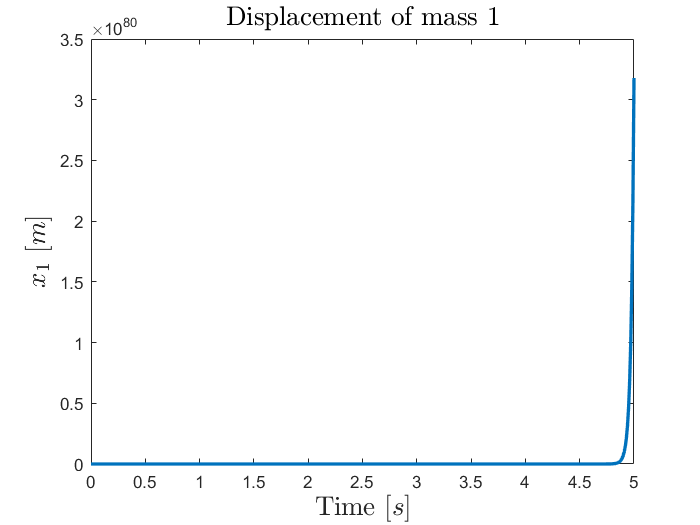


figure
plot(time,x1.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_1$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 1', 'FontSize',16,'Interpreter','latex');

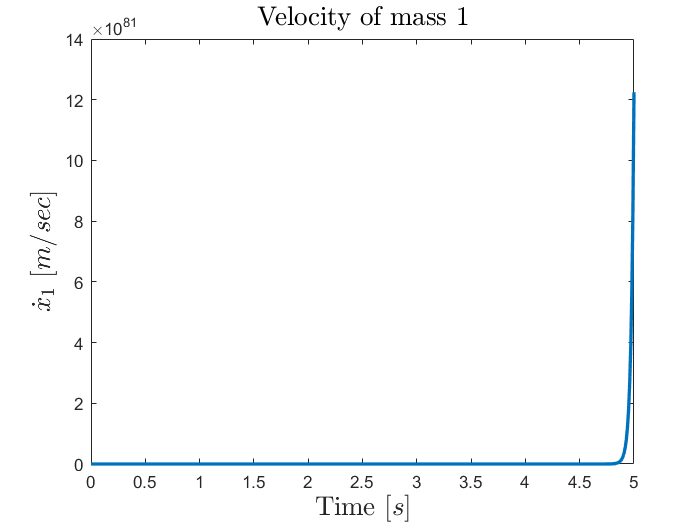


figure
plot(time,x1d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_1$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 1', 'FontSize',16,'Interpreter','latex');

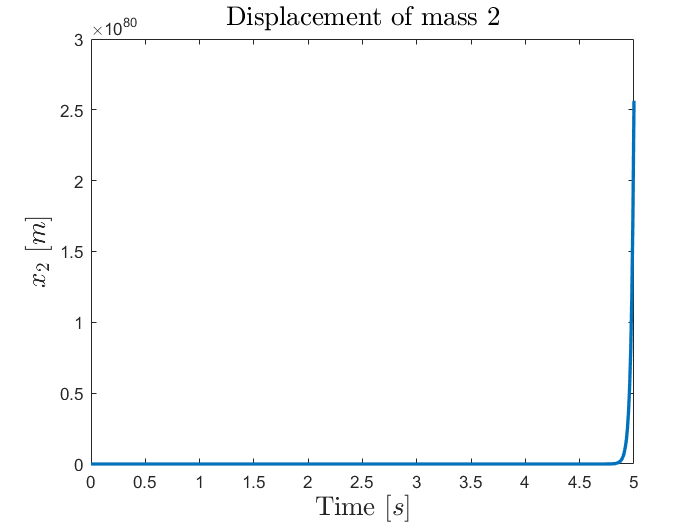


figure
plot(time,x2.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_2$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 2', 'FontSize',16,'Interpreter','latex');

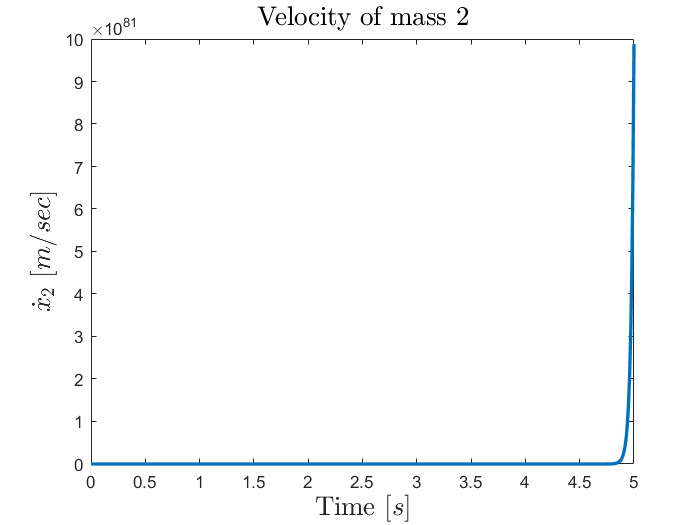


figure
plot(time,x2d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_2$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 2', 'FontSize',16,'Interpreter','latex');

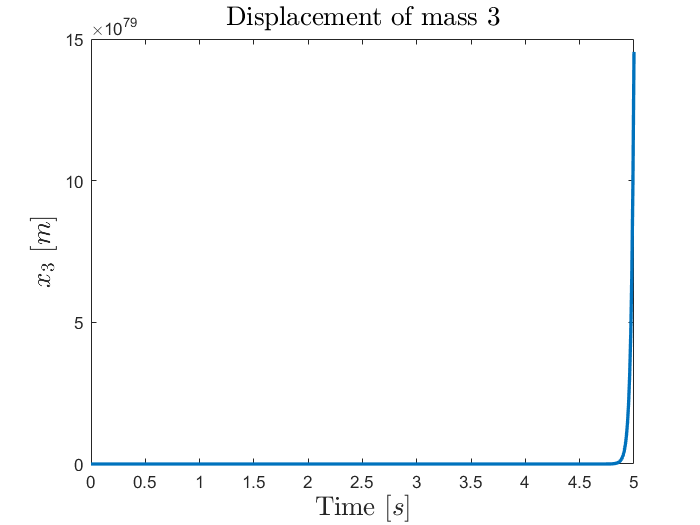


figure
plot(time,x3.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_3$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 3', 'FontSize',16,'Interpreter','latex');

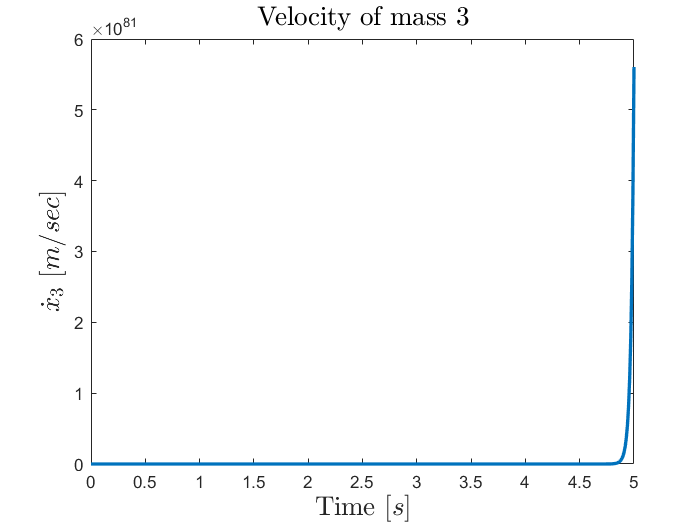


figure
plot(time,x3d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_3$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 3', 'FontSize',16,'Interpreter','latex');

Last, the system is simulated with $s_0$=1 mm. As it can be seen in the plots the system becomes unstable, i.e. the state variables do not settle to any equilibrium point but they keep growing unbounded. This can be explained by the fact that in very small distances the magnetic force is too large to allow the system to settle anywhere. Of course if the plots were real sensor data,  we should expect to see the states reaching a saturation level since the system is physically constraint.

**Problem 4**

What is the maximum lateral displacement experienced by the three masses when an initial condition of velocity of 5 mm/s acts on mass 3, assuming $s_0$=2 mm?

**Solution****:**

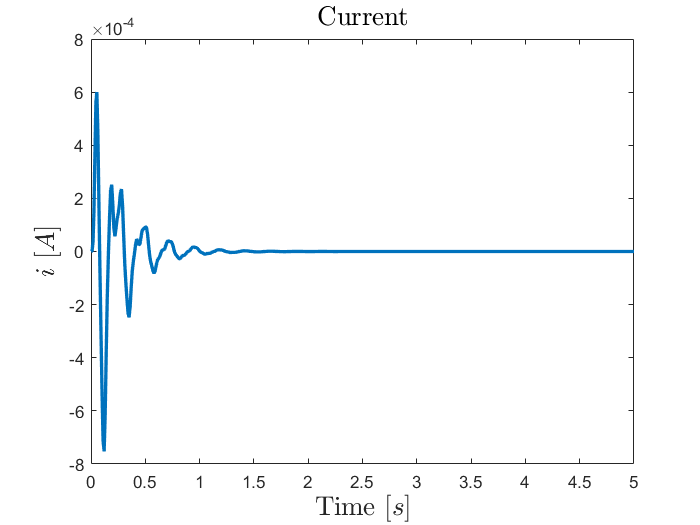

% initial conditions
x_0 = [0 0 0 0 0 0 0.005]';

x0 = 2e-3;          % displacement operation point

N = sqrt(L*2*x0 / (mu*A)); % estimate number of windings based on above formular

Ki = mu*N^2*A*ib / x0^2;
Ks = -mu*N^2*A*(ib^2)/x0^3;

Ax = [
        -R/L        0          Ki/L       0         0    0   0
          0         0             1       0         0    0   0
       -Ki/m1 -(k1 + k2 + Ks)/m1  0     k2/m1       0    0   0
          0         0             0       0         1    0   0
          0       k2/m2           0  -(k2 + k3)/m2  0  k3/m2 0
          0         0             0       0         0    0   1
          0         0             0     k3/m3       0 -k3/m3 0 ];
      
%% Simulations
sim('electroMagnetModelStateSpace');

%% Plots
time = i.time;

figure
plot(time,i.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$i$ $[A]$', 'FontSize',16,'Interpreter','latex');
title('Current', 'FontSize',16,'Interpreter','latex');


figure
plot(time,u.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$u$ $[V]$', 'FontSize',16,'Interpreter','latex');
title('Input voltage', 'FontSize',16,'Interpreter','latex');

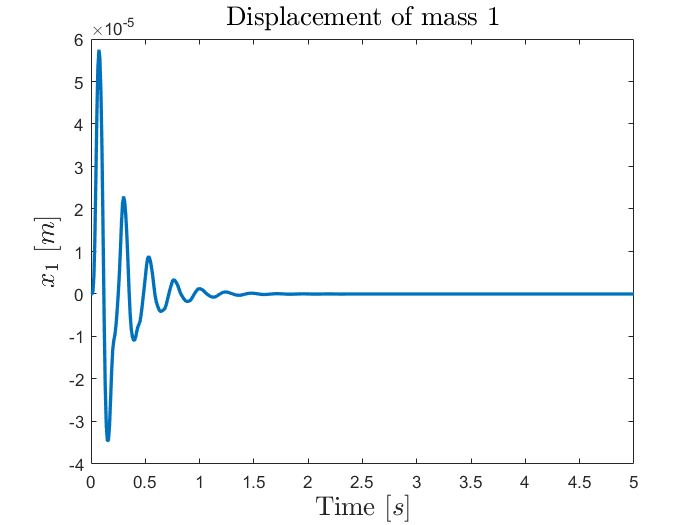


figure
plot(time,x1.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_1$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 1', 'FontSize',16,'Interpreter','latex');

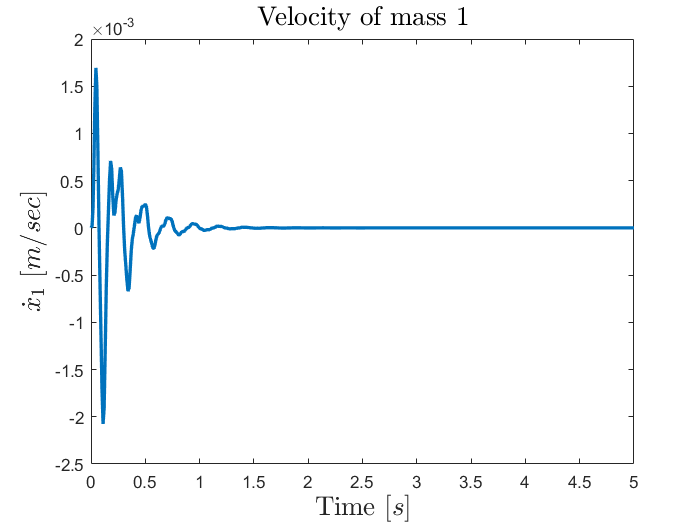


figure
plot(time,x1d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_1$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 1', 'FontSize',16,'Interpreter','latex');

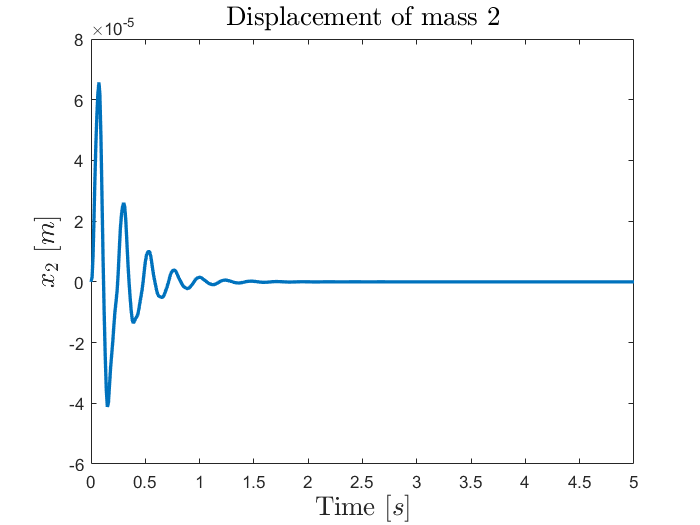


figure
plot(time,x2.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_2$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 2', 'FontSize',16,'Interpreter','latex');

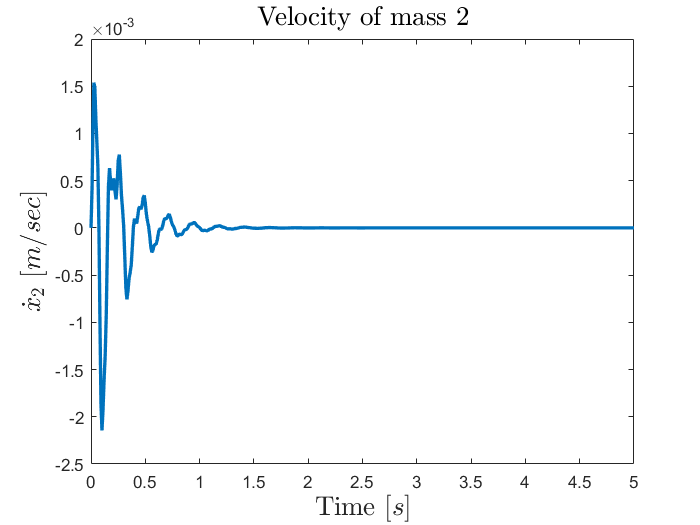


figure
plot(time,x2d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_2$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 2', 'FontSize',16,'Interpreter','latex');

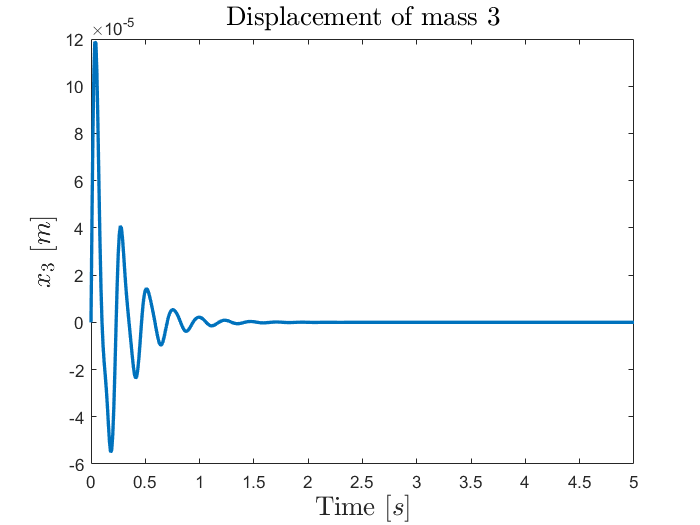


figure
plot(time,x3.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_3$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 3', 'FontSize',16,'Interpreter','latex');

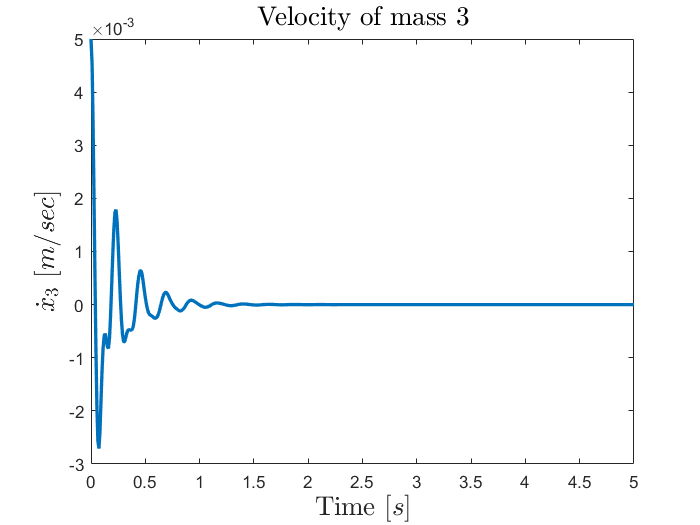


figure
plot(time,x3d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_3$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 3', 'FontSize',16,'Interpreter','latex');

From the time response of the state variables corresponding to the displacement of the masses from the simulation (the three plots on the left hand side) we can measure the maximum displacement for each mass as


$$x_{1,max}=5.74\cdot10^{-5}m\\
x_{2,max}=6.57\cdot10^{-5}m\\
x_{3,max}=1.18\cdot10^{-5}m$$


The displacement of the third (upper) mass is larger, almost double, in comparison to the other displacements. This is expected since the third mass on the top of the structure is globally more flexible, accumulating the deflection of the two lower masses. 

**Problem 5**

A step function $u(t)$=10 V is send to the electromagnets, assuming all initial conditions of lateral displacement, velocity and current nill. How will the three masses vibrate and how will the current change, i.e. amplitudes and frequencies.

**Solution****:**

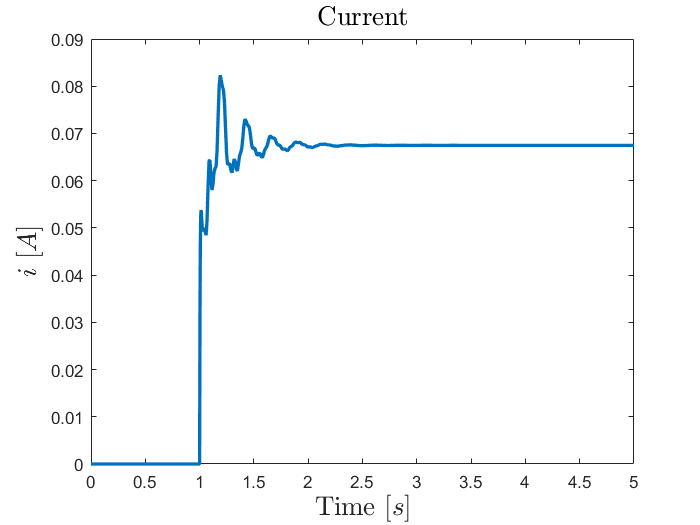

% initial conditions
x_0 = [0 0 0 0 0 0 0]';

% input
u_0 = 10;

%% Simulations
sim('electroMagnetModelStateSpace');

%% Plots
time = i.time;

figure
plot(time,i.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$i$ $[A]$', 'FontSize',16,'Interpreter','latex');
title('Current', 'FontSize',16,'Interpreter','latex');

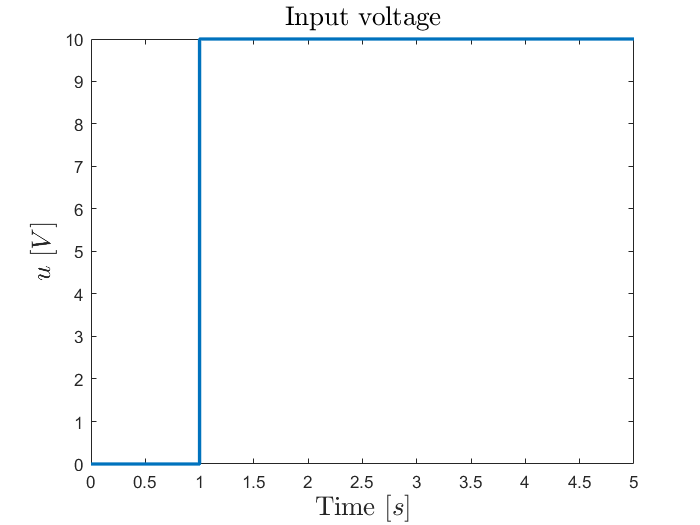


figure
plot(time,u.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$u$ $[V]$', 'FontSize',16,'Interpreter','latex');
title('Input voltage', 'FontSize',16,'Interpreter','latex');

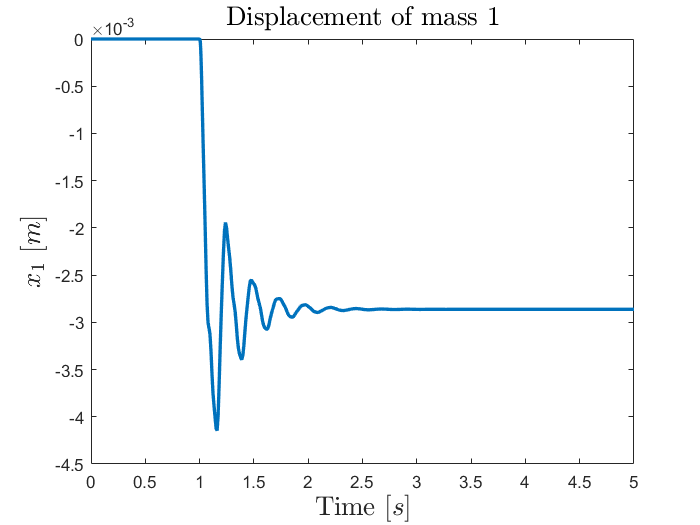


figure
plot(time,x1.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_1$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 1', 'FontSize',16,'Interpreter','latex');

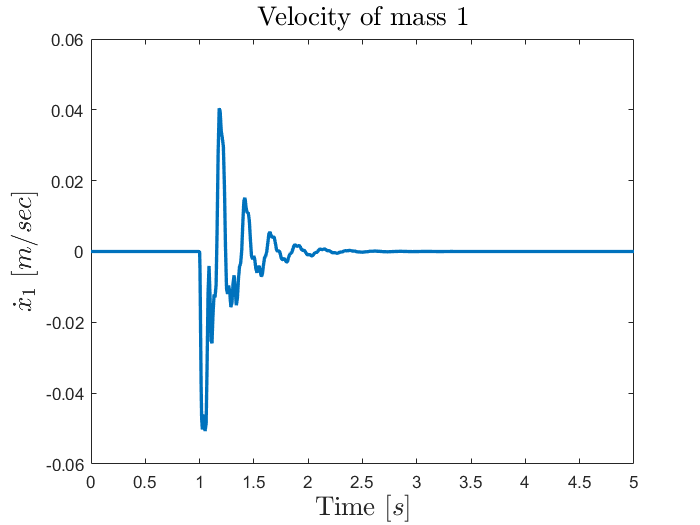


figure
plot(time,x1d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_1$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 1', 'FontSize',16,'Interpreter','latex');

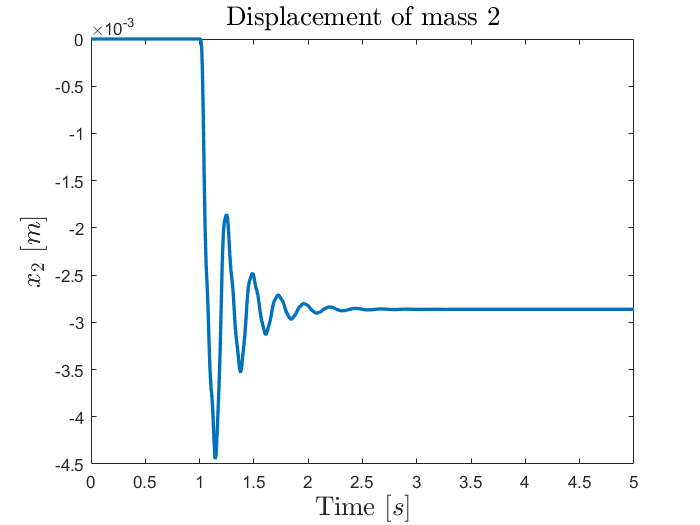


figure
plot(time,x2.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_2$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 2', 'FontSize',16,'Interpreter','latex');

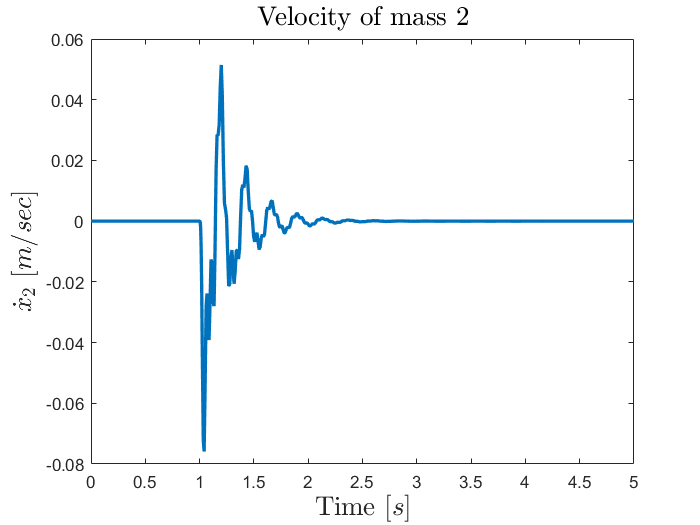


figure
plot(time,x2d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_2$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 2', 'FontSize',16,'Interpreter','latex');

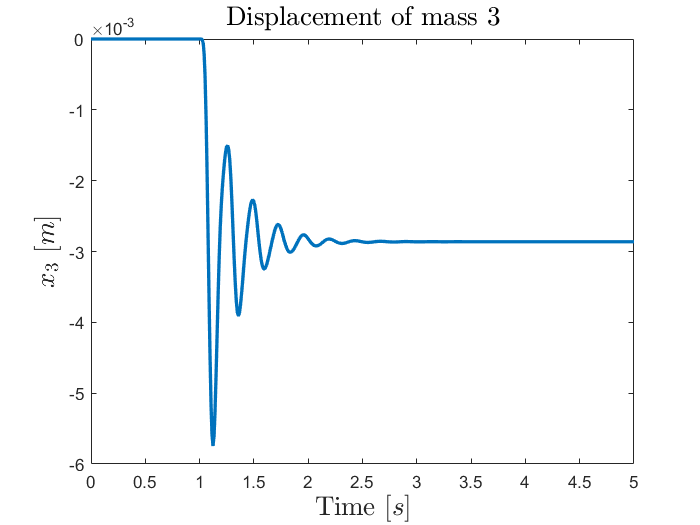


figure
plot(time,x3.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_3$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 3', 'FontSize',16,'Interpreter','latex');

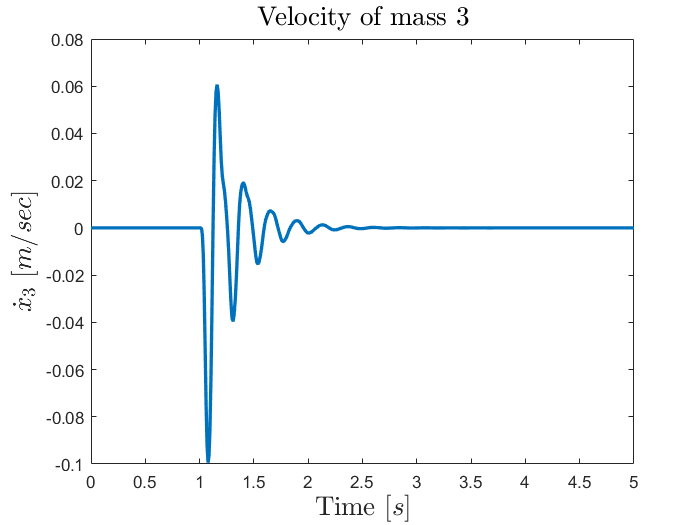


figure
plot(time,x3d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_3$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 3', 'FontSize',16,'Interpreter','latex');

As it is shown by the plots, after the transient behavior of the states has died out, the latter settle at a constant steady-state value. The velocities, as expected settle to zero, while the positions assume a nonzero value since there is a constant voltage that keeps exciting the system. The transient behavior can be described as a fading oscillatory response, which is expected, given that there is damping in the system. From the plots, by measuring the period (approximately) of the oscillations and the amplitude of the responses we can approximate the magnitude and the frequency of the signals. In the next lectures, when the modal analysis will be introduced, the relation between the oscillatory behavior of the responses and the eigenvalues of the system matrix $\textbf{A}$ will provide an accurate method of calculating the frequencies and amplitudes of the state responses.

**Problem 6**

Compare the obtained results from Group Work Module 2 with the results from this Group Work Module.

**Solution****:**

 It is the exact same results.